# System of Nonlinear Equations

## Task 1

In this activity, you'll visualize and solve the following system of equations] 

2xy−2y2=1

y3=cos(x)

Task

Visualize the equations in order to make an initial guess of the solution.

- Create a function handle `g` to an anonymous function for g(x,y)=2xy−2y2−1.

- Create a function handle `h`  to an anonymous function for h(x,y)=y3−cos(x).

- Plot `g` and `h` together with `fimplicit` on the interval -3 to 3.

Remember to use element-wise operators in your function definitions. 

g=@(x,y) 2.*x.*y-2.*(y.^2)-1

g = function_handle with value:
    @(x,y)2.*x.*y-2.*(y.^2)-1


h=@(x,y) y.^3-cos(x)

h = function_handle with value:
    @(x,y)y.^3-cos(x)


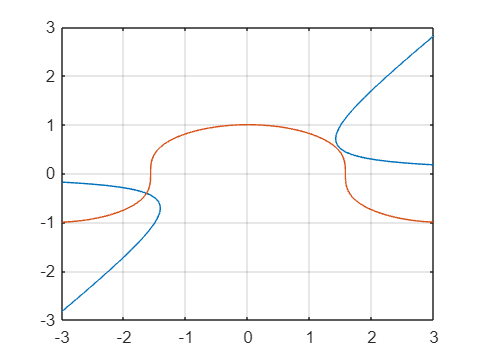

fimplicit(g,[-3,3])
hold on
fimplicit(h,[-3,3])
hold off
grid on

## Task 2

There is one root visible in your plot. 

Create an anonymous function handle for the system of equations. Then use `fsolve` to solve the system of equations for the visible root. Assign your result to the variable `wRoot`.

f=@(w)[g(w(1),w(2));
    h(w(1),w(2))]

f = function_handle with value:
    @(w)[g(w(1),w(2));h(w(1),w(2))]


w0=[-2 -1.5]

w0 =    -2.0000   -1.5000


z0=f(w0)

z0 =     0.5000
   -2.9589


wRoot=fsolve(f,w0)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


wRoot =    -1.6377   -0.4059


## Further Practice

The equations come very close to intersecting near (1.5,0.5). What happens if you try to find that "root"?

`notARoot` `=` `fsolve``(``mySystem``,``[``1.5``,``0.5``])`

Here, `fsolve` returns an approximate root, but also displays a warning that no  solution was found. Evaluate your function at the approximate root. How  close are the function values to zero?

`rootFunction``(``notARoot``)`

Even though `fsolve` did not find a solution, it still returned a result. It's important to  read the message displayed to make sure what it returns is really a  solution!

notARoot = fsolve(f,[1.5,0.5])


No solution found.

fsolve stopped because the problem appears regular as measured by the gradient,
but the vector of function values is not near zero as measured by the
value of the function tolerance.

<stopping criteria details>


notARoot =     1.4580    0.5185



f(notARoot)

ans =    -0.0257
    0.0268
